# Analysis of Variance (ANOVA) 

*Bart Krekelberg - Last Update Jan 2023.*

Analysis of Variance generalizes the idea of a two-sample test to determine the effect of a parameter (a **factor**) under experimental control that can take on multiple levels. For instance, the dosage of a drug, the area from which you record neural activity, or the time at which you performed a measurement. 

In this chapter we will look at the underlying methods as well as the Matlab functions that implement these tests in an efficient and easy to use manner. 

## One-Way ANOVA

Analysis of variance (ANOVA) is the logical next step from one-sample, to two-sample, to multi-sample tests. In an analysis of variance, we ask whether some treatment (called a factor) changes the *mean* of our measurements.

Let's consider an experiment in which you recorded the average neural actiity in multiple brain areas. Each measurement comes from a separate animal and you want to investigate whether brain areas have different mean activity levels. In formal term, you investigate the signficance of the factor 'brain area' on the activity . 

First let's sharpen our intuition by looking at some raw data:

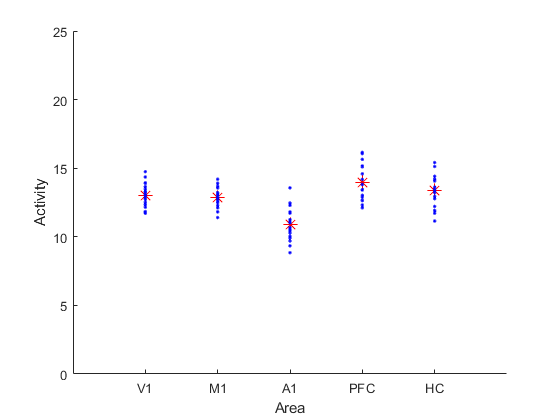

nrAreas = 5;
nrMeasurements = 20;
areaNames = {'V1','M1','A1','PFC','HC'};
areaActivity = 10+[3 2.5 1 4 3.3]; % Ground truth; the underlying means
measurementNoise = randn(nrMeasurements,nrAreas);
activity = repmat(areaActivity,[nrMeasurements 1]) +measurementNoise;
meanActivity = mean(activity);
figure(4);
clf;hold on
plot(1:nrAreas,meanActivity,'r*','MarkerSize',10);
plot(repmat(1:nrAreas,[nrMeasurements 1]),activity,'b.');
xlabel ('Area')
ylabel ('Activity');
set(gca,'XTick',1:nrAreas,'XTickLabel',areaNames,...
                    'XLim',[0 nrAreas+1],'Ylim',[0 25]);

Looking at these data you'd probably guess that the A1 activity is unusually low compared to the rest. But how do we quantify this? For comparison, look at this data set:

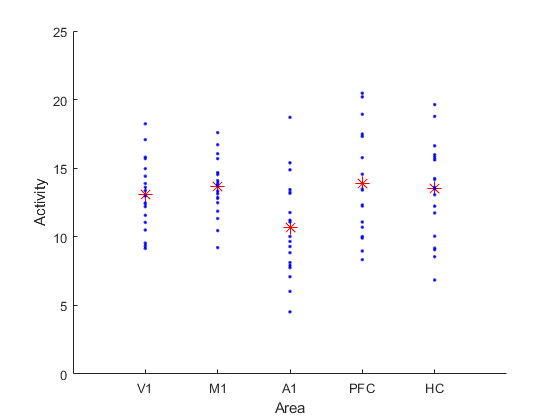

activity = repmat(areaActivity,[nrMeasurements 1]) + 3*measurementNoise;
meanActivity = mean(activity);
figure(5);
clf;hold on
plot(1:nrAreas,meanActivity,'r*','MarkerSize',10);
plot(repmat(1:nrAreas,[nrMeasurements 1]),activity,'b.');
xlabel ('Area')
ylabel ('Activity');
set(gca,'XTick',1:nrAreas,'XTickLabel',areaNames,...
                            'XLim',[0 nrAreas+1],'YLim',[0 25]);

Even though the measurements are still coming from underlying distributions with the same mean, I hope you agree this looks a lot less convincing. As you can see in the code, the only difference was the noise in the measurement. This is reflected in the figure as the spread of the samples around the mean. In other words, a larger spread (called variance) of each measurement around its mean should reduce your confidence that there is a real effect. 

The other important factor is the mean effect across treatmnents. For instance. We can go back to the original amount of noise but reduce the ground-truth mean activity differences:

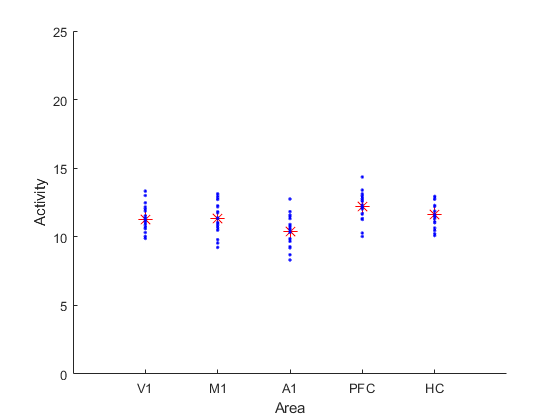

areaActivity = 10+0.5*[3 2.5 1 4 3.3]; % Ground truth; the underlying means
measurementNoise = randn(nrMeasurements,nrAreas);
activity = repmat(areaActivity,[nrMeasurements 1]) +measurementNoise;
meanActivity = mean(activity);
figure(4);
clf;hold on
plot(1:nrAreas,meanActivity,'r*','MarkerSize',10);
plot(repmat(1:nrAreas,[nrMeasurements 1]),activity,'b.');
xlabel ('Area')
ylabel ('Activity');
set(gca,'XTick',1:nrAreas,'XTickLabel',areaNames,...
                    'XLim',[0 nrAreas+1],'Ylim',[0 25]);

Now it is much less clear that A1 as less activity. 

Analysis of Variance captures these two intuitive measures by extracting a test statistic (conventionally called F) $$ F = \frac{variance-between-treatments}{variance-within-treatments} $$

If F~1 then the difference in activity between two areas is about the same as the difference between two measuremnts of activity within the same area (but different test animals). In other words, if F~1 it is unlikely that there is a meaningful difference among areas. 

The specific measure of *variance* in an ANOVA is the sum of squares, $$ ss   =\Sigma_i (y_i -\bar{y})^2 $$

Let's apply an ANOVA to the data from the first figure where A1 looked to be less active:

areaActivity = 10+[3 2.5 1 4 3.3]; % Ground truth; the underlying means
activity = repmat(areaActivity,[nrMeasurements 1]) +measurementNoise;
meanActivity = mean(activity);

Calculate the sum of squares between groups (`ssBetween`):

grandMean = mean(meanActivity);
ssBetween  = nrMeasurements*sum(((meanActivity-grandMean).^2));

The variance within treatments is calculated here using vectorized format; check carefully what is going on here!

ssWithin = sum(sum((activity-repmat(meanActivity,[nrMeasurements 1])).^2));

If you have many areas, then some of the differences are going to be large, just by chance. This is called the degrees of freedom (with more degrees of freedom, you have more opportunities to get a large number just by chance). The same is true for the number of measurements, if you do many measurements then it is likely that at least one of them is very high (due to chance). To calculate the test statistic, both the `ssBetween` and `ssWithin` are corrected for their respective degrees of freedom.

dofBetween = nrAreas-1;
dofWithin =nrAreas*(nrMeasurements-1);
F = (ssBetween/dofBetween)/(ssWithin/dofWithin)

F = 27.3853

This F is considerably larger than 1 which means it is unlikely to happen by chance. Formally, we compare it to the cumulative F distribution with the appropriate degrees of freedom (just as we did for the T statistic in the T-test):

pValue = fcdf(F,dofBetween,dofWithin,'upper')

pValue = 3.9996e-15

This shows that under the null hypothesis of no mean effect of area, the probabilty of observing an F that is as large or larger than the one we observed is `pValue`. In other words, we can safely reject the null hypothesis at a significance level of 0.01.

This manual calculation of the sum of squares, and the F statistic should give you some idea of how ANOVA's work, but these steps are all captured by the `anova1` function. You simply pass a matrix where each column corresponds to the measurements for one area:

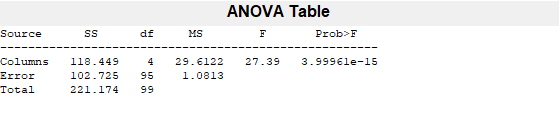

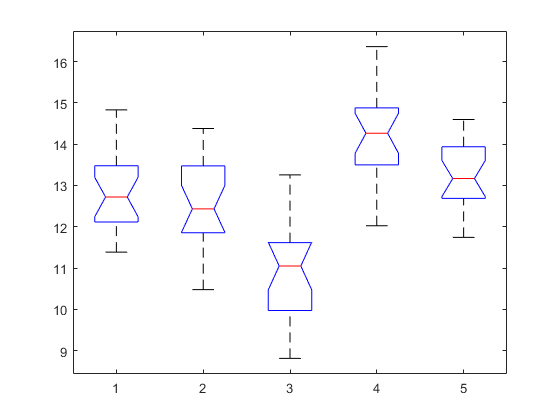

[p,table,stats] = anova1(activity);

By default `anova1` returns the p-value of the ANOVA, but also a full table of statistics that includes the sums of squares we calculated, as well as the degrees of freedom and the F statistic. In a paper you should report the result of the statistics not only as a p-value but with some more information about the specific test. For instance a good convention is to report this result as follows :

F(4,95) = 19.72, p<0.001

This shows that you used an F-test with 4 and 95 degrees of freedom. This automatically informs the reader that you had 5 treatent groups (brain areas in this case: dof+1). The fact that you had 20 measurements per group can be derived from the statement that the error degrees of freedom was 95. The actual F value is also informative as it shows that your effect is really large.

## Two-way ANOVA

In the ANOVA example above we looked at the influence of one factor (brain area) on the mean of the measurement (brain activity). This is called a one-way ANOVA. In a different experiment you may be interested in the differences in activity among brain areas in wild type and genetically modified animals. This experiment has two factors (brain area and wild-type vs. mutant) and we analyze it with a two-way analysis of variance. 

The principles of the two-way ANOVA are analogous to those of the one-way: you estimate the variance within "treatment" groups, and compare it to the variance across groups. If the ratio (F) is very different from 1, then it is unlikely to have happened by chance. Let's simulate an example:

nrAreas             = 5;
nrTypes             = 2; % WT and Mutant
nrMeasurements      = 20;

areaActivityWT    = 10+0.5*[3 2.5 1 4 3.3]; % Ground truth; means for wild type
areaActivityMutant= areaActivityWT +2     ; % Ground truth; means for mutants
measurementNoise  = randn(nrMeasurements,nrAreas,nrTypes);
activity          = repmat(cat(3,areaActivityWT,areaActivityMutant),[nrMeasurements 1 1 ]) ...
                                + measurementNoise;

% Calculate the sums of squares
grandMean           = mean(activity(:));
meanActivity        = mean(activity);
meanPerArea         = mean(mean(activity),3);
meanPerType         = mean(mean(activity),2);
ssWithin            = sum(sum(sum((activity-repmat(meanActivity,[nrMeasurements 1 1])).^2))); 
ssBetweenAreas      = nrMeasurements*nrTypes* ...
                            sum(sum(((meanPerArea-grandMean).^2),2),3);
ssBetweenTypes      = nrMeasurements*nrAreas* ...
                            sum(sum(((meanPerType-grandMean).^2),2),3);

`ssBetweenAreas` expresses the average change in mean activity between areas averaged over wild types and mutants.  `ssBetweenTypes` on the other hand expresses the mean activity change between wild types and mutants averaged across all areas.

We can only consider such differences to be "real" if they are larger than the averge differencs measured within each of the groups. That latter measure is `ssWithin`, so the next step is to compute the F-statistic. Just as before, this is the ratio of the measured effect (variance across groups) to the typical noise in our measurements (variance within groups). The only difference is that we now have two such measures:

dofBetweenAreas = nrAreas-1;
dofBetweenTypes = nrTypes-1;
dofWithin =nrAreas*nrTypes*(nrMeasurements-1);
areasF = (ssBetweenAreas/dofBetweenAreas)/(ssWithin/dofWithin)

areasF = 12.7927

typesF = (ssBetweenTypes/dofBetweenTypes)/(ssWithin/dofWithin)

typesF = 194.5532

Both F's are considerably larger than 1 which means that they are unlikely to happen by chance. Formally, we again compare these F's to the cumulative F distribution:

pAreas = fcdf(areasF,dofBetweenAreas,dofWithin,'upper')

pAreas = 3.0633e-09

pTypes = fcdf(typesF,dofBetweenTypes,dofWithin,'upper')

pTypes = 6.5842e-31

These values show that the so-called main effect of area is significant at the `pAreas` level, and the main effect of type is significant at the `pTypes` level. You would report these findings separately with two statements like F(1,190) = `areasF` (p<0.001) and F(4,190) = `typesF` (p<0.001).

## Interactions

The two main effects investigated above quantify how much areas change the activity *on average* and how much type changes activity *on average*. But what if mutants have an unusually active HC, and an unusually inactive A1? 

We'll simulate that the A1 in a wild type matches the activity of the HC in the mutant and vice versa.

ixHC  = find(strcmpi('HC',areaNames));
ixA1 = find(strcmpi('A1',areaNames));
areaActivityWT      = 10+0.5*[3 2.5 1 4 3.3]; % Ground truth; means for wild type
areaActivityMutant = areaActivityWT;  % Mutant is the same as WT
areaActivityMutant([ixHC ixA1]) = areaActivityWT([ixA1 ixHC]); % Except that A1 and HC are swapped
activity            = repmat(cat(3,areaActivityWT,areaActivityMutant),[nrMeasurements 1 1 ]) ...
                        + measurementNoise; % Add measurement noise

Now we repeat the identical analysis of variance we did above. 

grandMean           = mean(activity(:));
meanActivity        = mean(activity);
meanPerArea         = mean(mean(activity),3);
meanPerType         = mean(mean(activity),2);
ssWithin            = sum(sum(sum((activity-repmat(meanActivity,[nrMeasurements 1 1])).^2))); 
ssBetweenAreas      = nrMeasurements*nrTypes*sum(sum(((meanPerArea-grandMean).^2),2),3);
ssBetweenTypes      = nrMeasurements*nrAreas*sum(sum(((meanPerType-grandMean).^2),2),3);
dofWithin =nrAreas*nrTypes*(nrMeasurements-1);
areasF = (ssBetweenAreas/dofBetweenAreas)/(ssWithin/dofWithin);
typesF = (ssBetweenTypes/dofBetweenTypes)/(ssWithin/dofWithin);
pAreas = fcdf(areasF,dofBetweenAreas,dofWithin,'upper')

pAreas = 1.0212e-04

pTypes = fcdf(typesF,dofBetweenTypes,dofWithin,'upper')

pTypes = 0.5277

As before, there is a significant effect of areas, but now the ANOVA claims that there is no significant effect of type (`pTypes>0.05`). Because we created the data we know this is incorrect, but why does the ANOVA not find the difference in firing rate in the HC and A1 that we introduced in the Mutant? 

A figure may help to clarify this. 

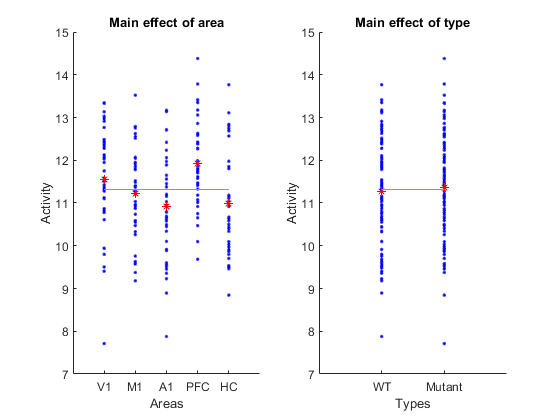

figure(5);clf;
subplot(121)
hold on
allPerArea = reshape(permute(activity,[1 3 2]),[nrMeasurements*nrTypes nrAreas]);
plot(1:nrAreas,allPerArea,'b.');
plot(1:nrAreas,meanPerArea,'r*');
plot(get(gca,'XLim'),[grandMean grandMean],'g');
xlabel('Areas')
ylabel 'Activity'
set(gca,'XLim',[0 nrAreas+1],'XTick',1:nrAreas,'XTickLabel',areaNames);
title 'Main effect of area'

subplot(122)
hold on
allPerType = reshape(activity,[nrMeasurements*nrAreas nrTypes]);
plot(1:nrTypes,allPerType,'b.');
plot(1:nrTypes,squeeze(meanPerType),'r*');
plot(get(gca,'XLim'),[grandMean grandMean],'g');
xlabel('Types')
ylabel 'Activity'
set(gca,'Xlim',[0 nrTypes+1],'XTick',[1 2],'XTickLabel',{'WT','Mutant'});
title 'Main effect of type'

The data points in subplot 1 show everything that the ANOVA uses to determine significance of a main effect of area. In essence the ANOVA esimates whether the variation of the red asterisks (the means per area) relative to the green line (grand mean) is large compared to the difference between the blue points (individual measurements) per area.

Note that this analysis ignores type; for each area the data points that are used to estimate the (within) variance include the ones from the wild type and the mutant. But even when combining the data across types, the activity in A1 looks quite differen from the grand mean; that contributes to the significance of the main effect of area.

Analogolously, when determining the main effect of type, the ANOVA does not distinguish among areas. As subpot 2 shows, the *average* difference between the types and the grand mean is small (and much less than the variance within a type), and the ANOVA concludes that there is no effect of type. 

The failure of the ANOVA to detect the effect we introduced results from the fact that the ANOVA above can only detect main effects in one factor (type) that are different *on average* across all levels of the other factor (area). Put differently, the ANOVA correctly failed to reject the null hypothesis that the types have different activity on average.  *On average* the activities are the same. In general, however, we may want to consider null hypotheses that are not so restrictive. For instance, we may be interested in effects of type that occur for only some of the areas. Testing such null hypotheses requires the calculation of the  *interaction* sum of squares. 

Here is the calculation:

typeEffect = repmat(meanPerType,[1 nrAreas 1])-grandMean;
areaEffect = repmat(meanPerArea,[1 1 nrTypes])-grandMean;
alreadyExplained = (typeEffect+areaEffect+grandMean);
ssInteraction = nrMeasurements*(sum(sum(((meanActivity- alreadyExplained).^2),2),3));

Look carefully how the sum of squares of the interaction is defined. First we determine the "effect" of type; that is how much each type differs from the overall mean (irrespective the area). Then we determine the effect of area : how much the rate changes in each area (irrespective its type) These are essentially the calculations we use to determine the sum of squares corresponding to each of the two facotrs (i.e. main effects). In the `ssInteraction` calculation we ask how much variation in the `meanActivity` remains after taking into accout the two main effects that we've already considered (as well as the grand mean). Hence this term captures variation that could not be captured by the main effects,; we call it the interaction term. 

Graphically we can represent this as:

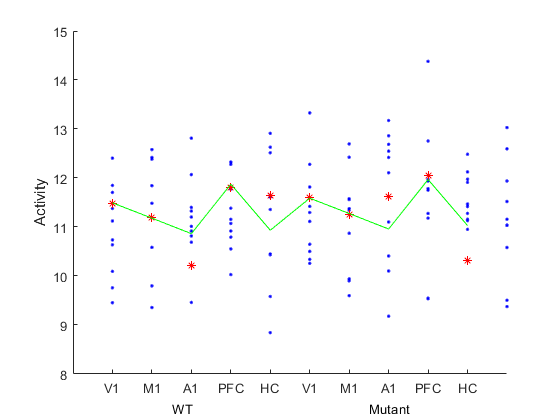

figure(6);clf
hold on
% Plot individual measurements for each combination of area and type
plot(reshape(activity,[nrMeasurements nrTypes*nrAreas]),'b.') 
% Use : to stretch the matrix into areas for WT then areas for Mutant
plot(meanActivity(:),'r*'); 
plot(alreadyExplained(:),'g') 
ylabel 'Activity'
set(gca,'XLim',[0 2*nrAreas+1],'XTick',1:2*nrAreas,'XTickLabel',cat(2,areaNames,areaNames));
text(2.5,7.3,'WT')
text(7.5,7.3,'Mutant')

The green line shows how we would expect the data to vary if there only were main effects of area and type (plus the grand mean). The red asterisks show the actual means for each of the conditions, and the `ssInteraction` quantifies how different the asterisks are from the green line. 

Once we have the sum of squares of the interaction, testing for its significance follows the same procedure as before (and uses the spread of each of the measurements around their mean: the variance of the blue dots):

dofInteraction = (nrAreas-1)*(nrTypes-1);
interactionF = (ssInteraction/dofInteraction)/(ssWithin/dofWithin);
pInteraction  = fcdf(interactionF,dofInteraction,dofWithin,'upper')

pInteraction = 2.6659e-06

`interactionF` is larger than 1 and therefore this is unlikely to happen by chance. `pInteraction` gives the corresponding p-value. The interpretation of the fact that  |pInteraction < 0.05 | is that for at least some areas, the activity in the wild type is different from the activity in the mutant. 

Matlab has 2 built-in functions that can perform a two-way anova. `anova2` and  `anovan`. I find the format of the `anovan` function most intuitive. Moreover, it can do higher order ANOVAs (three-way, four-way etc.) and unbalanced ANOVAs. Unbalanced ANOVAs are used to analyse data set where the number of measurements is not the same for each combination of factors. For instance, if you measured only 10 wild type animals but 15 mutants.

## Post-hoc tests

The conclusions you can draw on the basis of an ANOVA are quite limited. For instance in the case of a signficant main effect (be it in one-way or two-way ANOVA), you can only conclude that there is some change in the means that is related to the factor. In the one-way ANOVA example we could conclude that mean brain activity was not the same across all areas, but we could **not** conclude that A1 was less active than the others! The same is true for the initial example of the two-way ANOVA: the main effect of area and type allowed us to conclude that brain activity was not the same across areas and not the same across types, but it did not allow any conclusion about which areas were different. The significant iinteraction term allowed the conclusion that the way in which brain activity varies acroos area was different in the mutants than the wild types, but it did not allow us to say anything about which area was particularly affected. 

In other words, ANOVAs support statements about the factors of an experiment ('area'), not about the individual levels ('a1','pfc',...) of those factors. The sole exception is a factor in an ANOVA with two groups (which is the same as a T-Test); if that main effect is significant, then it is ok to say that the group with the largest mean had a significantly higher mean than the group with the lowest mean. 

In general, if you want to make a more specific statement such as "the PFC was more active" then you need to perform a so-called post-hoc test. In Matlab the anova functions return all the arguments you need for post-hoc tests. For simplicity, let's return to the one-way anova example. 

areaActivity = 10+[3 2.5 1 4 3.3]; % Ground truth; the underlying means
measurementNoise = randn(nrMeasurements,nrAreas);
activity = repmat(areaActivity,[nrMeasurements 1]) +measurementNoise;
[p,table,stats] = anova1(activity,[],'off'); % Dont display the ANOVA window

The `stats` output of the `anova1` function can be passed to the `multcompare` function to perform post-hoc tests. For instance:

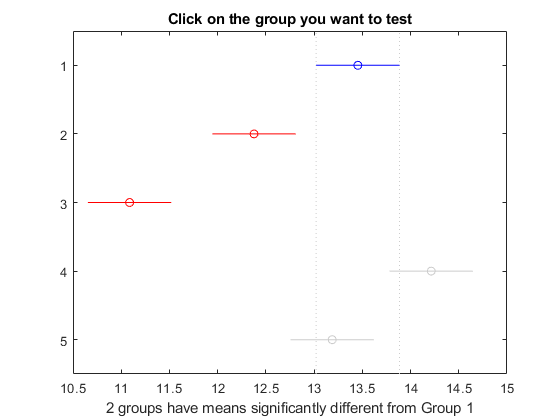

comparisons = multcompare(stats);

By default this function creates a figure showing the means of each of the groups (areas in our case) with error bars that show the approximate confidence intervals for the mean (i.e. the true mean of the group could be anywhere within those intervals). Areas whose errorbars overlap are not significantly different, areas whose errorbars do not overlap are significantly different. 

Inside Matlab this figure is interactive. If you click on one of the areas, the areas that have a significantly different mean from it are shown in red and those whose mean activity is not significantly different are in grey.

In this example figure, group 1 ('V1') is selected. The colors show that V1 activity is significantly different from A1 activity, but not from the other areas. The p-values associated with each comparison are returned in the the last column of the comparisons array. 